clearvars;
eeglab; close;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\anhtn\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.3 to the path
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.02' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "ERPLAB" v10.02 (see >> help eegplugin_erplab) - new version 10.04 available
EEGLAB: adding "Fileio" v20240111 to the path
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "PICARD" v1.0 to the path
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eeg

trials = {'001-AOE', '002-AOE', '003-AO'};

filepath = 'C:\\Users\\anhtn\\OneDrive - PennO365\\Documents\\GitHub\\analysis\\Datasets\\';

ALLEEG_1 = cell(1,3);
for i=1:length(trials)
    filename = [trials{i} '-curated.set']; % manually type to select dataset
    ALLEEG_1{i} = pop_loadset('filename', filename, 'filepath', filepath);
end

pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\001-AOE-curated.set ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\002-AOE-curated.set ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\003-AO-curated.set ...



trial_N = 3;
EEG = ALLEEG_1{trial_N};

pop_epoch():204 epochs selected
Epoching...
pop_epoch():204 epochs generated
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
................................
Click on each trace for channel/component index


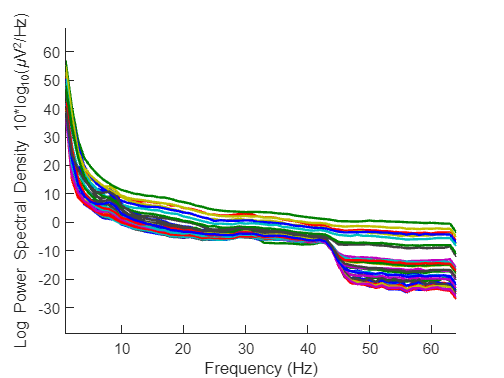

base_tlen = [0 8];
cond_plot_spectra(EEG, {EEG.urevent.type}, base_tlen, ...
        [],  {{EEG.chanlocs.labels}}, 1, "", [], 'on');

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..
Click on each trace for channel/component index


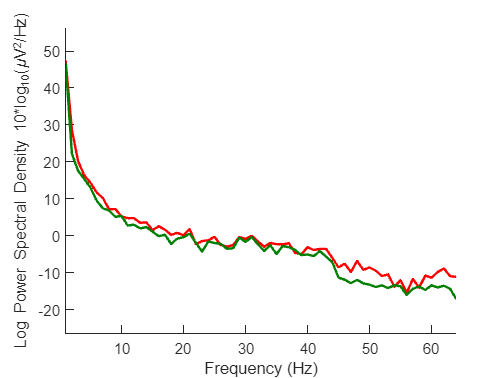


% cond_plot_spectra(EEG, {EEG.urevent.type}, base_tlen, ...
%         [],  {[1 19 17 21 30 18 16]}, 1, "", [], 'on');
cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        [],  {{'C3', 'C4'}}, 1, "", [], 'on');

pop_epoch():204 epochs selected
Epoching...
pop_epoch():204 epochs generated
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 30 channel(s)...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
..
Click on each trace for channel/component index


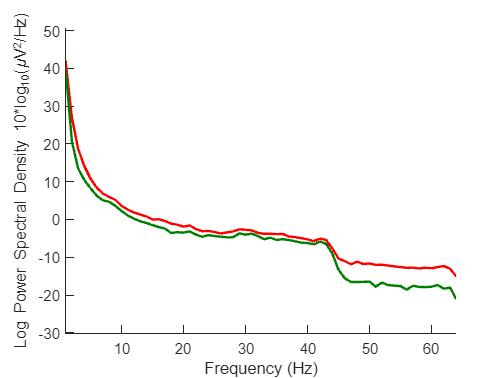

cond_plot_spectra(EEG, {EEG.urevent.type}, [0 4], ...
        [],  {{'C3', 'C4'}}, 1, "", [], 'on');

## Preprocessing 

% compute average reference
% EEG= pop_reref( EEG, []);

% EEG = pop_eegfiltnew( EEG,'locutoff',0.5);
% EEG = pop_eegfiltnew( EEG,'hicutoff', 45);


Visual inspection

if trial_N == 3
    EEG = pop_select(EEG, 'rmchannel', [1 19 17 21 30 18 16]); %high-amplitude artifact (Pz, f4)
elseif trial_N == 2
    EEG = pop_select(EEG, 'rmchannel', [30]);
elseif trial_N == 1
    EEG = pop_select(EEG, 'rmchannel', [29 32 3]);
end

Removing 7 channel(s)...



% clean data using the clean_rawdata plugin: only remove bad channels
% EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,...
%     'LineNoiseCriterion',4,'Highpass','off','BurstCriterion','off',...
%     'WindowCriterion','off','BurstRejection','off','Distance','Euclidian');


% recompute average reference interpolating missing channels (and removing
% them again after average reference - STUDY functions handle them automatically)
EEG = pop_reref( EEG,[],'interpchan',[]);

Re-referencing data



% % Clean data using the clean_rawdata plugin: only run ASR - not use this
% now because it can remove event markers
% EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off',...
%     'LineNoiseCriterion','off','Highpass','off','BurstCriterion',40,...
%     'WindowCriterion',0.5,'BurstRejection','on','Distance','Euclidian', ...
%     'WindowCriterionTolerances',[-Inf 7]);

%for 003-aoe
EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off',...
    'LineNoiseCriterion','off','Highpass','off','BurstCriterion',40,...
    'WindowCriterion','off','BurstRejection','off','Distance','Euclidian');

Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 7.5% (167 seconds) of the data.
eeg_insertbound(): 195 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 174 blocks..............................................................................................................................................................................
Use vis_artifacts to compare the cleaned data to the original.
Done.


% 
% % compute average reference
EEG= pop_reref( EEG, []);

Re-referencing data


### Run ICA to remove artifactual components

% EEG = pop_runica(EEG, 'icatype','runica', 'extended',1,'interrupt','on');
% plugin_askinstall('picard', 'picard', 1); % install Picard plugin
EEG = pop_runica(EEG, 'icatype','picard','concatcond','on','options',{'pca',-1});

         is not modeling the entire data, only the PCA-reduced data.
Attempting to convert data matrix to double precision for more accurate ICA results.
Decreasing data dimension from 25 to 24 using PCA...
iteration 1, gradient norm = 0.0414
iteration 2, gradient norm = 0.03464
iteration 3, gradient norm = 0.0478
iteration 4, gradient norm = 0.03564
iteration 5, gradient norm = 0.03107
iteration 6, gradient norm = 0.02428
iteration 7, gradient norm = 0.02421
iteration 8, gradient norm = 0.02166
iteration 9, gradient norm = 0.02719
iteration 10, gradient norm = 0.00941
iteration 11, gradient norm = 0.006305
iteration 12, gradient norm = 0.003352
iteration 13, gradient norm = 0.001547
iteration 14, gradient norm = 0.001048
iteration 15, gradient norm = 0.0005366
iteration 16, gradient norm = 0.00025


% run ICLabel and flag artifactual components
EEG  = pop_iclabel(EEG , 'default');

ICLabel: extracting features...
ICLabel: calculating labels...
ICLabel: saving results...


EEG  = pop_icflag( EEG ,[NaN NaN;0.7 1;0.7 1;NaN NaN;NaN NaN;NaN NaN;NaN NaN]);

1 components flagged for rejection, to reject them use Tools > Remove components from data


% eegplot( EEG , 1, 1, 1);
EEG  = pop_subcomp( EEG , [], 0); % remove bad components

Computing projection and removing 1 components ....


Remove components with high percentage of Eye labels

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.........................
Click on each trace for channel/component index


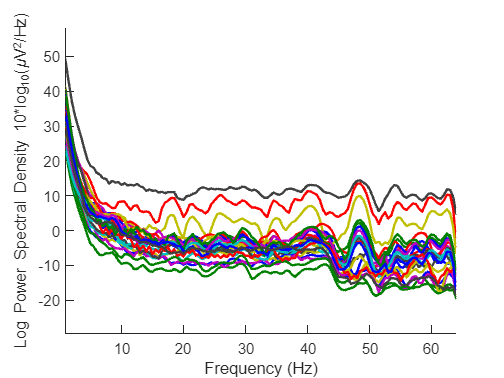

base_tlen = [0 8];
cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        [],  {{EEG.chanlocs.labels}}, 2, "", [], 'on');

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 23 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
..
Click on each trace for channel/component index


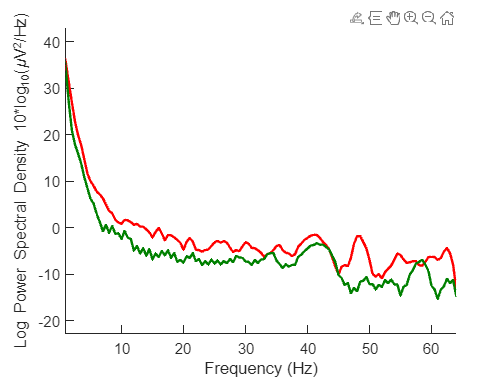

cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        [],  {{'C3', 'C4'}}, 2, "", [], 'on');

pop_epoch():204 epochs selected
Epoching...
pop_epoch():204 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 23 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
..
Click on each trace for channel/component index


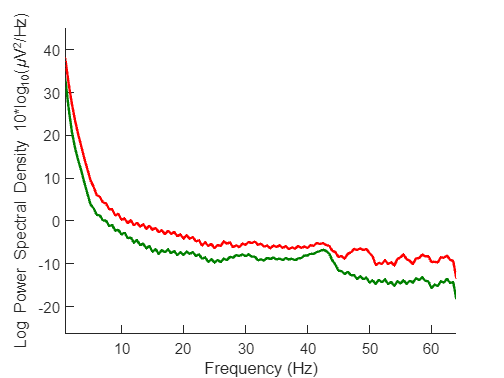

cond_plot_spectra(EEG, {EEG.urevent.type}, base_tlen, ...
        [],  {{'C3', 'C4'}}, 2, "", [], 'on');

% pop_saveset(EEG, 'filename', [trials{i} '-preprocessed.set'], 'filepath', filepath)


function [spectra,freqs,specstd] = cond_plot_spectra(EEG, events_cell, tlen, freqs, chanlocs, freqfac, plottitle, filepath, toPlot)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    
    if length(chanlocs) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', chanlocs{1});
        if string(toPlot) == "on"
            figure; title(plottitle);
        end
        [spectra,freqs,speccomp,contrib,specstd] = pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');

    elseif length(chanlocs) == 2
        EEG_cond_RH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1});
        EEG_cond_LH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1}); 
        figure; sgtitle(plottitle);
        subplot(211); 
        pop_spectopo(EEG_cond_RH, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
        subplot(212); 
        pop_spectopo(EEG_cond_LH, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
    end
    % save_figures(filepath, plottitle, toPlot)
end


%===================================================
function OUTEEG = cond_epoch(EEG, events_cell, tlen)
    % events_cell
    EEG_epoch = pop_epoch(EEG, events_cell, tlen, 'verbose', 'off');
    OUTEEG = pop_rmbase(EEG_epoch, [0 0.5]*1000);

end